Alen Mehmedbegovic - January 18th 2024

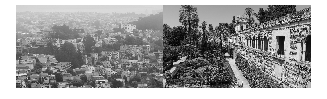

highfreq = im2double(rgb2gray(imread("sevilla.jpg")));

lowfreq = imread("foggysf1.jpg");
lowfreq = lowfreq(500:1399, 1000:2599, :);
lowfreq = im2double(rgb2gray(lowfreq));
imshow([lowfreq highfreq])

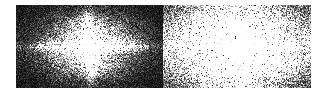


low_fou = fft2(lowfreq);
high_fou = fft2(highfreq);
imshow([fftshift(abs(low_fou)) fftshift(abs(high_fou))]/ 50)

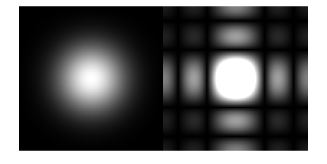

% In lhs low_freq image, most frequency components are in center which is
% low frquency. In rhs high_freq image there are still low frequencys but
% they're alot more spread out from the edges 
% If there are many edges, high frequencies. If there are stale colours,
% low frequency 

% Convolution theorem states that the fourier transform of a convolution *
% between two functions is the product of their fourier transforms 
% F(g*h) = F(g)F(h)  <==> F^-1(g*h) = F^-1(g)F^-1(h)
% Convolution in spatial domain is equalivalent to multiplication in
% frequency domain
% Because convolution is a filtering kernel, we can just multiply the two
% fourier transforms of the two images together and get the same filtering
% result 

% Now let's examine fequency responses of filters
gaus = fspecial('gaussian', 10, 1);
box = ones(5);
imshow([fftshift(abs(fft2(gaus, 622, 622))) fftshift(abs(fft2(box, 622, 622)))/10])

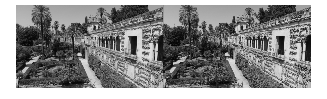

% Fourier transform of our gaussian is another gaussian, fourier transform
% of box filter is our sinc(x) function, meaning filtering with gaussian
% will only keep low filter components, but filtering with box will keep
% some high frequency ones aswell
box = box/sum(box(:));
hf_box = imfilter(highfreq, box);
hf_gaus = imfilter(highfreq, gaus);
imshow([hf_box hf_gaus]);

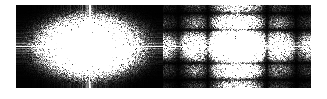

% On rhs we have harsh edges and jumping in general. Let's look at
% frequency response 
hf_box_fou = fft2(hf_box);
hf_box_gaus = fft2(hf_gaus);
imshow([fftshift(abs(hf_box_gaus)) fftshift(abs(hf_box_fou))]/10)

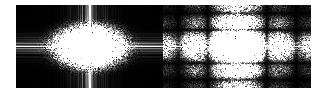


gaus = fspecial('gaussian', 10, 1.5);
hf_gaus = imfilter(highfreq,gaus);
hf_box_gaus = fft2(hf_gaus);
imshow([fftshift(abs(hf_box_gaus)) fftshift(abs(hf_box_fou))]/10)

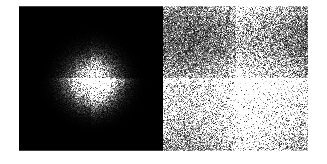

gaus_fou = fft2(gaus, 622, 622);
high_fou = high_fou(1:622, 400:1021, :); % Technically cheating but
flit_im_fou = gaus_fou.*high_fou;
imshow([abs(fftshift(flit_im_fou)) abs(fftshift(high_fou))]/50);

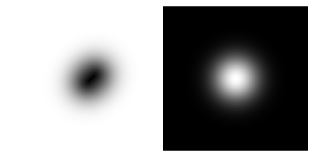

flit_hf = ifft2(flit_im_fou); % Convert it back 
% ERROR when showing because of mismatching dim

% We can make low pass kernel by subtracting kernel from image
oneflit = zeros(size(gaus));
oneflit(6,6) = 1;
imshow([abs(fftshift(fft2(oneflit - gaus, 622,622))) abs(fftshift(gaus_fou))])

% They're opposites of each other! High pass filter at end of lecture 